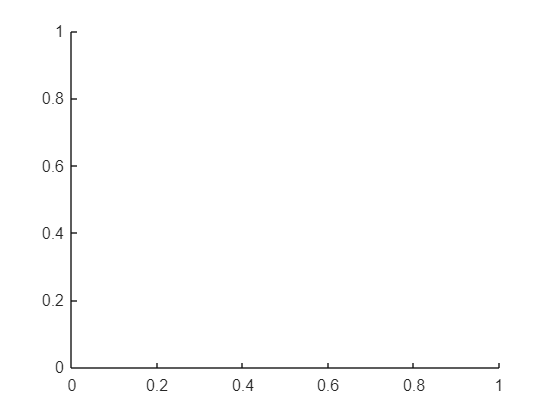

residual: 496.118 
residual: 376.492 
residual: 331.334 
residual: 306.953 
residual: 290.538 
residual: 276.429 
residual: 264.48 
residual: 253.845 
residual: 246.475 
residual: 242.868 
residual: 240.514 
residual: 236.166 
residual: 230.485 
residual: 223.464 
residual: 215.776 
residual: 209.533 
residual: 206.061 
residual: 204.427 
residual: 202.592 
residual: 201.591 
residual: 200.449 
residual: 199.046 
residual: 197.065 
residual: 194.388 
residual: 191.291 
residual: 187.902 
residual: 185.274 
residual: 184.045 
residual: 183.064 
residual: 180.811 
residual: 178.009 
residual: 176.309 
residual: 174.357 
residual: 171.657 
residual: 168.83 
residual: 165.689 
residual: 162.886 
residual: 160.313 
residual: 157.878 
residual: 155.418 
residual: 153.401 
residual: 150.621 
residual: 147.287 
residual: 143.767 
residual: 141.094 
residual: 139.277 
residual: 137.546 
residual: 135.848 
residual: 134.2 
residual: 132.321 
residual: 130.148 
residual: 127.676 
residual: 124.96

clear; close all; clc;

% files to run from
% for project 4 the mesh comes from project 3
MeshFileName = "2D_Mesh_41_by_21"; % file to read mesh from
%MeshFileName = "2D_Mesh_81_by_41"; % file to read mesh from
%MeshFileName = "2D_Mesh_321_by_161"; % file to read mesh from
%MeshFileName = "2D_Mesh_641_by_321"; % file to read mesh from
ParamFileName = "project_4_parameters_V_0"; % file to read parameters from
BCFileName = "project_4_BoundaryConditions_V_0"; % file to read for boundary conditions

% load mesh, simulation parameters, and boundary conditions
load(MeshFileName);
load(ParamFileName);
load(BCFileName);

% compute the number of cells in each direction
IDimetion = size(Mesh,1) - 1;
JDimention = size(Mesh,2) - 1;

% initialize mesh and solver variables
% NOTE TO SELF: there may
[Q, Vol, AreaVI, AreaVJ] = Initialize(Mesh, IDimetion, JDimention, Q_in);


%TODO: when a function is complete move it into its own file

% solver

%initialize loop variables
converged = false;
itteration = 0;
Q_star = Q; % initilize the Q_star matrix to the same value as Q
resinit = Residual(Q, Q_in, IDimetion, JDimention, Vol, AreaVI, AreaVJ, gamma, order, clf);
residual_magnitude_initial = abs(norm(resinit(:,:,1)));
residual_history = [];

figure;% for ploting
stepsPerPlot = 100; % plotting setting

while ~converged % itterate until convergence
    itteration = itteration +1; % keep track of what itteration we are on 
    % SSP-RK2

    

    % reconstruction
    [Q_i_triangle, Q_i_square, Q_j_triangle, Q_j_square] =  Reconstruction(Q, IDimetion, JDimention, AreaVI, AreaVJ, Q_in, gamma, order);
    % compute timeStep
    Delta_t = getTimeStep(Q_i_triangle, Q_i_square, Q_j_triangle, Q_j_square, Vol, AreaVI, AreaVJ, clf, gamma, globalTimeStepping);

    Res = Residual(Q, Q_in, IDimetion, JDimention, Vol, AreaVI, AreaVJ, gamma, order);
    Q_star = Q + Delta_t .* Res;
    Res_star = Residual(Q_star, Q_in, IDimetion, JDimention, Vol, AreaVI, AreaVJ, gamma, order, clf);
    Q = 1/2 * (Q + Q_star + Delta_t .* Res_star);

    % test of convergence
    fprintf("residual: %g \n", abs(norm(Res(:,:,1))));
    residual_magnitude_current = abs(norm(Res(:,:,1)));
    residual_history(itteration) = residual_magnitude_current;
    if residual_magnitude_current <= residual_magnitude_initial*10^(-6)
        converged = true;
    end
    if itteration >= maxItterationLimit % stop here
        break;
    end


    %plot
    if mod(itteration,stepsPerPlot) == 0
        figure(1);
        % surf is the classic and looks good
        surf(Mesh(2:end,2:end,1), Mesh(2:end,2:end,2), Q(:,:,1), "FaceAlpha",.75); view([0,0,90]); colorbar; colormap("hot"); axis equal;
        
        hold on;
        %         %vectSpars = 5
        %         %quiver(Mesh(2:vectSpars:end,2:vectSpars:end,1), Mesh(2:vectSpars:end,2:vectSpars:end,2), Q(1:vectSpars:end,1:vectSpars:end,2)./Q(1:vectSpars:end,1:vectSpars:end,1), Q(1:vectSpars:end,1:vectSpars:end,3)./Q(1:vectSpars:end,1:vectSpars:end,1), "Color",[1,1,1]);
        %         hold off;
        %         streamlineSparsity = 10
        %         verts = stream2(Mesh(2:end,2:end,1), Mesh(2:end,2:end,2), Q(:,:,2)./Q(:,:,1), Q(:,:,3)./Q(:,:,1), Mesh(2:streamlineSparsity:end, 2:streamlineSparsity:end, 1), Mesh(2:streamlineSparsity:end, 2:streamlineSparsity:end, 2));
        %         streamline(verts);
        axis = gca;
        set(axis, "Color", [0,0,0]);
        xlim(axis,[-2,1.1]) % actual max should be 1.0995
        ylim(axis,[0,4])
        drawnow;
    end
end


% display competion method
if converged
    disp("converged");
else
    disp("not converged");
end

% post processing



%this one is crude and good for ploting things on top of
%contourf(Mesh(2:end,2:end,1), Mesh(2:end,2:end,2), Q(:,:,1)), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]);

% create folder for results
fileSaveName = sprintf("%gx%g O%g", size(Mesh,1), size(Mesh,2), order); % name for files
% name ofr folder (keep folder within a Results folder)
folderName = sprintf("Results\\Results %s %s", fileSaveName, datestr(datetime('now','TimeZone','local','Format','d-MMM-y HH-mm-ss Z'),'dd-mmm-yyyy HH-MM-SS'))

mkdir(folderName) % create the folder


% plot convergence history
figure;
semilogy(residual_history); title("Convergence History"); xlabel("Itteration"); xlabel("Density Residual");
saveas(gcf, sprintf("%s\\%s convergence histroy", folderName, fileSaveName), "jpg");


% This one is beautiful
figure;
grid_x = zeros([IDimetion,JDimention]); grid_y = zeros([IDimetion,JDimention]);
% stretch the edge of the grid to cover domain
grid_x(1:IDimetion,:) = Mesh(1:end-1,1:end-1,1); grid_x(IDimetion,:) = Mesh(end,1:end-1,1); grid_x(:,JDimention) = Mesh(1:end-1,end,1);
grid_y(1:IDimetion,:) = Mesh(1:end-1,1:end-1,2); grid_y(IDimetion,:) = Mesh(end,1:end-1,2); grid_y(:,JDimention) = Mesh(1:end-1,end,2);
% plot the beutiful graph (looks better than surf but takes way longer to compute)
contourf(grid_x, grid_y, Q(:,:,1),1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); 
axis equal; set(gca, "Color", [0,0,0]); colorbar;

% compute some stuff for plotting
[V, p, E, rho, c] = getFlowProperties(Q, gamma); u = V(:,:,1); v = V(:,:,2); V_mag = u.^2+v.^2; M = V_mag./c;

[V, p, E, rho, c] = getFlowProperties(Q, gamma); u = V(:,:,1); v = V(:,:,2); V_mag = u.^2+v.^2; M = V_mag./c;
vectSpars = 20; hold on; quiver(Mesh(2:vectSpars:end,2:vectSpars:end,1), Mesh(2:vectSpars:end,2:vectSpars:end,2), Q(1:vectSpars:end,1:vectSpars:end,2)./Q(1:vectSpars:end,1:vectSpars:end,1), Q(1:vectSpars:end,1:vectSpars:end,3)./Q(1:vectSpars:end,1:vectSpars:end,1), "Color",[0,1,0]); hold off;
streamlineSparsity = 25; verts = stream2(grid_x(:,:), grid_y(:,:), Q(:,:,2)./Q(:,:,1), Q(:,:,3)./Q(:,:,1), grid_x(2:streamlineSparsity:end, 2:streamlineSparsity:end), grid_y(2:streamlineSparsity:end, 2:streamlineSparsity:end)); streamline(verts);

% calling this  fuction will save the current figure to the results folder
% for this run case with the name of the axis
% saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");

figure; contourf(grid_x, grid_y, V_mag,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("V_mag"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, u,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("u"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, v,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("v"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, p./rho,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("T"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, p,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("p"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, M,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("M"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, rho,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("rho"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");
figure; contourf(grid_x, grid_y, E,1000,"LineWidth",.001,"EdgeAlpha",0), colormap("hot"); axis equal; set(gca, "Color", [0,0,0]); colorbar; title("E"); saveas(gcf, sprintf("%s\\%s %s", folderName, fileSaveName, get(get(gca,"Title"),"String")), "jpg");

% save the final timeStep
save(sprintf("%s\\%s %s", folderName, fileSaveName, "Q"), "Q");
% should do a better job with these
params = struct("clf", clf, "order", order, "gamma", gamma, "Q_in", Q_in, "globalTimeStepping", globalTimeStepping, "maxItterationLimit", maxItterationLimit);
save(sprintf("%s\\%s %s", folderName, fileSaveName, "Params"), "params");

function Res = Residual(Q, Q_in, ID, JD, Vol, AreaVI, AreaVJ, gamma, order, CFL)
    %Res = zeros([ID,JD,4]); % unnesseary to preallocate
    % Compute resuidual
    IFlux = computeIFLux(Q, ID, JD, Vol, AreaVI, gamma, order);
    Res = IFlux(2:end, :, :) .* AreaVI(2:end,:,1)  - IFlux(1:end-1, :, :) .* AreaVI(1:end-1,:,1);
    JFlux = computeJFLux(Q, ID, JD, Vol, AreaVJ, Q_in, gamma, order);
    Res = Res + JFlux(:, 2:end, :) .* AreaVJ(:, 2:end, 1) - JFlux(:, 1:end-1, :) .* AreaVJ(:, 1:end-1, 1);
    Res = -Res./Vol;
    
    % Compute Delta_t
    
end

function Delta_t = getTimeStep(Q_i_triangle, Q_i_square, Q_j_triangle, Q_j_square, Vol, AreaVI, AreaVJ, clf, gamma, globalTimeStepping)
    % get velocitices and speed of sounds at cell boundaries
    [V_i_triangle, ~, ~, ~, c_i_triangle] = getFlowProperties(Q_i_triangle, gamma);
    [V_i_square, ~, ~, ~, c_i_square] = getFlowProperties(Q_i_square, gamma);
    [V_j_triangle, ~, ~, ~, c_j_triangle] = getFlowProperties(Q_j_triangle, gamma);
    [V_j_square, ~, ~, ~, c_j_square] = getFlowProperties(Q_j_square, gamma);
    
    % compute normal velocities
    V_n_i_triangle = getVNormal(V_i_triangle, AreaVI);
    V_n_i_square = getVNormal(V_i_square, AreaVI);
    V_n_j_triangle = getVNormal(V_j_triangle, AreaVJ);
    V_n_j_square = getVNormal(V_j_square, AreaVJ);
    
    % compute average normal velocities (note these are at cell boundaries starting at index-1/2)
    V_n_i_av = (V_n_i_triangle + V_n_i_square) / 2;
    V_n_j_av = (V_n_j_triangle + V_n_j_square) / 2;
    
    % compute average speed of sounds (note these are at cell boundaries starting at index-1/2)
    c_i_av = (c_i_triangle + c_i_square) / 2;
    c_j_av = (c_j_triangle + c_j_square) / 2;
    
    % compute timestep
    denom_i = (abs(V_n_i_av(2:end,:,:)) + c_i_av(2:end,:,:)) .* AreaVI(2:end,:,1) + (abs(V_n_i_av(1:end-1,:,:)) + c_i_av(1:end-1,:,:)) .* AreaVI(1:end-1,:,1);
    denom_j = (abs(V_n_j_av(:,2:end,:)) + c_j_av(:,2:end,:)) .* AreaVJ(:,2:end,1) + (abs(V_n_j_av(:,1:end-1,:)) + c_j_av(:,1:end-1,:)) .* AreaVJ(:,1:end-1,1);
    
    Delta_t = (2 * clf * Vol) ./ (denom_i +denom_j);
    
    if globalTimeStepping
        Delta_t = repmat(min(Delta_t,[],"all"),size(Delta_t));
    end
end



function IFlux = computeIFLux(Q, ID, JD, Vol, AreaVI, gamma, order)
    % initialize
    IFlux = zeros([ID+1, JD, 4]);
    % reconstruction
    [Q_triangle, Q_square] = reconstruct_I(Q, ID, JD, AreaVI, gamma, order); % have these passed in
    % compute rusanov flux
    IFlux = Russanov(Q_square, Q_triangle, AreaVI, gamma);
end

function JFlux = computeJFLux(Q, ID, JD, Vol, AreaVJ, Q_in, gamma, order)
    % initialize
    JFlux = zeros([ID, JD+1, 4]);
    % reconstruction
    [Q_triangle, Q_square] = reconstruct_J(Q, ID, JD, AreaVJ, Q_in, gamma, order); % have these passed in
    % compute rusanov flux
    JFlux = Russanov(Q_square, Q_triangle, AreaVJ, gamma);
end

% reconstruct both I and J
% currently first order only
function [Q_i_triangle, Q_i_square, Q_j_triangle, Q_j_square] =  Reconstruction(Q, ID, JD, AreaVI, AreaVJ, Q_in, gamma, order)
    [Q_i_triangle, Q_i_square] = reconstruct_I(Q, ID, JD, AreaVI, gamma, order);
    [Q_j_triangle, Q_j_square] = reconstruct_J(Q, ID, JD, AreaVJ, Q_in, gamma, order);
end

% reconstruct_I
% currently first order only
function [Q_triangle, Q_square] = reconstruct_I(Q, ID, JD, AreaVI, gamma, order) 
    % reconstruct I
    Q_triangle = zeros([ID+1, JD, 4]); % left of cell right of boundary
    Q_square = zeros([ID+1, JD, 4]);
    
    % minmod limiter (for second order reconstruction)
    function slope = minmod_i(Q)
        Q_p = Q(3:end,:,:); % Q plus one index
        Q_m = Q(1:end-2,:,:); % Q minus index
        Q_c = Q(2:end-1,:,:); % Q central index
        slope = max(0, min(1, (Q_p-Q_c) ./ (Q_c-Q_m) )) .* (Q_c-Q_m); % compute slope via minmod limiter
    end

    % compute the left side of the cells
    if order == 1
        Q_triangle(2:end-2, :, :) = Q(2:end-1, :, :); % apply the values to most of the domain
    elseif order == 2
        %do order 2 stuff
        Q_triangle(2:end-2, :, :) = Q(2:end-1,:,:) - 1/2 * minmod_i(Q);
    else
        fprintf("order %g not supported", order);
    end
    % near the edge of the domain a first order aproximation must be used
    Q_triangle(1, :, :) = Q(1, :, :);
    Q_triangle(end-1, :, :) = Q(end, :, :);
    
    % compute the left side of the cells
    if order == 1
        Q_square(3:end-1, :, :) = Q(2:end-1, :, :); % apply the values to most of the domain
    elseif order == 2
        %do order 2 stuff
        Q_square(3:end-1, :, :) = Q(2:end-1, :, :) + 1/2 * minmod_i(Q);
    else
        fprintf("order %g not supported", order);
    end
    % near the edge of the domain a first order aproximation must be used
    Q_square(2, :, :) = Q(1, :, :);
    Q_square(end, :, :) = Q(end, :, :);

    %computed boundary conditions

    % compute the left boundary (supersonic exit boundary)
    Q_square(1,:,:) = symmetryBoundary(Q_triangle(1, :, :), gamma);
    % compute the left boundary (supersonic exit boundary)
    Q_triangle(end,:,:) = superSonicExitBoundary(Q_square(end, :, :));
    
    % for fun use aerospike
    useAerospike = false;
    if useAerospike
        n(1,:,1) = AreaVI(1,:,2); n(1,:,2) = AreaVI(1,:,3);
        Q_square(1,:,:) = slipWallBoundary(Q_triangle(1, :, :), n, gamma);
    end
    % for debug just use supersonic exit everywhere
    %Q_square(1,:,:) = superSonicExitBoundary(Q_triangle(1, :, :));
    %Q_triangle(end,:,:) = superSonicExitBoundary(Q_square(end, :, :));
end



function [Q_triangle, Q_square] = reconstruct_J(Q, ID, JD, AreaVJ, Q_in, gamma, order)
    % reconstruct I
    Q_triangle = zeros([ID, JD+1, 4]); % left of cell right of boundary
    Q_square = zeros([ID, JD+1, 4]);

    % minmod limiter (for second order reconstruction)
    function slope = minmod_j(Q)
        Q_p = Q(:,3:end,:); % Q plus one index
        Q_m = Q(:,1:end-2,:); % Q minus index
        Q_c = Q(:,2:end-1,:); % Q central index
        slope = max(0, min(1, (Q_p-Q_c) ./ (Q_c-Q_m) )) .* (Q_c-Q_m); % compute slope via minmod limiter
    end
    
    % compute the left side of the cells
    if order == 1
        Q_triangle(:, 2:end-2, :) = Q(:, 2:end-1, :); % apply the values to most of the domain
    elseif order == 2
        %do order 2 stuff
        Q_triangle(:, 2:end-2, :) = Q(:, 2:end-1, :) - 1/2 * minmod_j(Q);
    else
        fprintf("order %g not supported", order);
    end
    % near the edge of the domain a first order aproximation must be used
    Q_triangle(:, 1, :) = Q(:, 1, :);
    Q_triangle(:, end-1, :) = Q(:, end, :);
    
    % compute the left side of the cells
    if order == 1
        Q_square(:, 3:end-1, :) = Q(:, 2:end-1, :); % apply the values to most of the domain
    elseif order == 2
        %do order 2 stuff
        Q_square(:, 3:end-1, :) = Q(:, 2:end-1, :) + 1/2 * minmod_j(Q);
    else
        fprintf("order %g not supported", order);
    end
    % near the edge of the domain a first order aproximation must be used
    Q_square(:, 2, :) = Q(:, 1, :);
    Q_square(:, end, :) = Q(:, end, :);

    %computed boundary conditions

    % compute the left boundary (supersonic exit boundary)
    n(:,1,1) = AreaVJ(:,1,2); n(:,1,2) = AreaVJ(:,1,3);
    Q_square(:,1,:) = slipWallBoundary(Q_triangle(:, 1, :), n, gamma);
    % compute the left boundary (supersonic exit boundary)
    Q_triangle(:,end,:) = superSonicInletBoundary(Q_square(:,end,:), Q_in);
    
    % for debug just use supersonic exit everywhere
    %Q_square(:,1,:) = superSonicExitBoundary(Q_triangle(:, 1, :));
    %Q_triangle(:,end,:) = superSonicExitBoundary(Q_square(:, end, :));
end

% computes the russanov flux from the values on the left and right side
% of a boundary
% TAKES: flux on left of boundary Q_L on riht of boundary Q_R, Length
% of Row/column to be evaluated Len, vetor of lengths and normals AreaV
% RETURNS: russanvo flux FLUX
function Flux = Russanov(Q_L, Q_R, AreaV, gamma)
    %compute disipation
    [V_L, ~, ~, ~, c_L] = getFlowProperties(Q_L, gamma);
    [V_R, ~, ~, ~, c_R] = getFlowProperties(Q_R, gamma);

    V_n_L = getVNormal(V_L, AreaV);
    V_n_R = getVNormal(V_R, AreaV);
    
    V_n_av = (V_n_L + V_n_R) / 2;
    
    c_av = (c_L + c_R) / 2;

    dissipation = (abs(V_n_av) + c_av)/2 .* (Q_R - Q_L); % disipation term

    function normalFlux = getNormalFlux(Q_face, AreaV, gamma)
        % computes the flux in the normal direction
        [V, p, E, rho, ~] = getFlowProperties(Q_face, gamma); % get relevant flow peroperties
        V_n = getVNormal(V, AreaV); % get normal velocity
        u = V(:,:,1); v = V(:,:,2);
        N_x = AreaV(:,:,2); N_y = AreaV(:,:,3);
        normalFlux(:,:,1) = rho.*V_n;
        normalFlux(:,:,2) = rho.*u.*V_n + p.*N_x;
        normalFlux(:,:,3) = rho.*v.*V_n + p.*N_y;
        normalFlux(:,:,4) = V_n.*(E + p);
        %normalFlux = [rho.*V_n, rho.*u.*V_n + p.*N_x, rho.*v.*V_n + p.*N_y, V_n.*(E + p)]; % get normal flux
    end

    % compute russanov flux
    Flux = 1/2 * (getNormalFlux(Q_L, AreaV, gamma) + getNormalFlux(Q_R, AreaV, gamma)) - dissipation;
end

function V_n = getVNormal(V, AreaV)
    u = V(:,:,1);
    v = V(:,:,2);
    n_x = AreaV(:,:,2);
    n_y = AreaV(:,:,3);
    V_n = u .* n_x + v .* n_y;
%     u = V(:,1);
%     v = V(:,2);
%     n_x = AreaV(:,2);
%     n_y = AreaV(:,3);
%     V_n = u .* n_x + v .* n_y;
end


function Q_B = slipWallBoundary(Q_CV, n, gamma)
    % compute the value of Q on the far side of a slip wall boundary
    [V, p, ~, rho, ~] = getFlowProperties(Q_CV, gamma);
    u = V(:,:,1);
    v = V(:,:,2);

    rho_B = rho;
    p_B = p;

    n_x = n(:,:,1);
    n_y = n(:,:,2);

    u_B = u - 2 * dot(V,n,3) .* n_x;
    v_B = v - 2 * dot(V,n,3) .* n_y;
    V_B(:,:,1) = u_B;
    V_B(:,:,2) = v_B;


    Q_B = getQ(V_B, p_B, rho_B, gamma);
end

function Q_B = symmetryBoundary(Q_CV, gamma)
    % computes the value on the opposing side of a bonadary from a known
    % value on the inside of the boundary
    [V, p, ~, rho, ~] = getFlowProperties(Q_CV, gamma);
    u = V(:,:,1);
    v = V(:,:,2);

    rho_B = rho;
    p_B = p;
    u_B = u;
    v_B = -v;

    V_B(:,:,1) = u_B;
    V_B(:,:,2) = v_B;
    
    %Q_B = getQ(V_B, p_B, rho_B, gamma); % commented for debug

    %for debug
    %[V_foo, p_foo, ~, rho_foo, ~] = getFlowProperties(Q_B, gamma);

    % hypothetically this should be true 
    Q_B(:,:,1) = Q_CV(:,:,1); % rho_B = rho_CV
    Q_B(:,:,2) = Q_CV(:,:,2); % rho_B * u_B = rho_CV * u_CV
    Q_B(:,:,3) = -Q_CV(:,:,3); % rho_B * v_B = rho_CV * -v_CV
    Q_B(:,:,4) = Q_CV(:,:,4); % E_B = E_CV -> true from conservation of energy

    % turn this on for aerospike
    %Q_B = getQ(V_B, p_B, rho_B, gamma); % commented for debug
end

function Q_B = superSonicExitBoundary(Q_CV)
    % computes the value on the far side of a supersonic exit boundary.
    Q_B = Q_CV;
end

function Q_B = superSonicInletBoundary(Q_CV, Q_in)
    % computes the value on the far side of a supersonic exit boundary.
    Q_B = ones(size(Q_CV));
    for i = 1:4
        Q_B(:,:,i) = Q_B(:,:,i) * Q_in(i);
    end
end